# CS3200 Introduction to Scientific Computing

## Assignment #4 - 

Author: Robert Li    

uID:u1212360

## Problem 1: Exploring LU Decomposition & Sparse Matrices

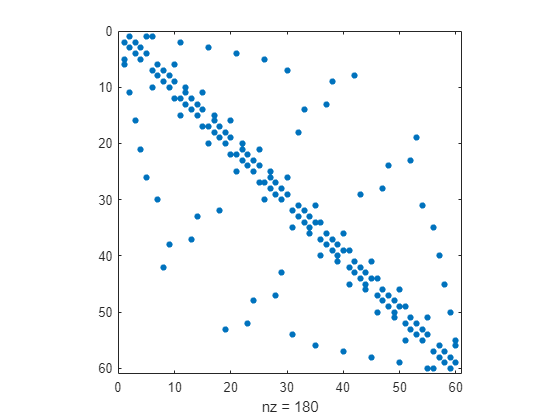

clear all, close all, clc, clf
B=bucky;  % Load the bucky data and save as matrix B
b=ones(length(B));  % use the ones function to create a b function
spy(B)   %Plot the data

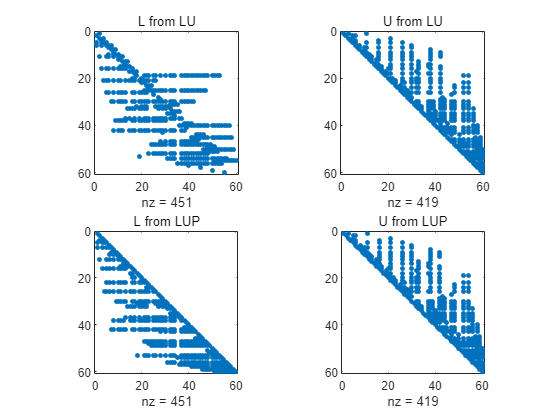

[L,U]=lu(B);   %LU decomposition on B
[l,u,p]=lu(B);  %%LUP decomposition on B
%Create 2x2 subplot
subplot(2,2,1)  
spy(L) %Plot L fom LU decomposition
title('L from LU')
subplot(2,2,2)
spy(U)  %Plot L=U fom LU decomposition
title('U from LU')
subplot(2,2,3)
spy(l)  %Plot L fom LUP decomposition
title('L from LUP')
subplot(2,2,4)
spy(u)  %%Plot U fom LUP decomposition
title('U from LUP')

x=inv(U)*inv(L)*b  %calcute x in two steps

x =    0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.333333333333333   0.33333333333

R=B*x-b  %to check the result

R = 	1.0e+-14 *

   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   0.133226762955019   

How did I implemented: This question I simply construct the lu and used spy to make the 

decoposition as comment described above.

b) The data in B is stored as two columns. First column contains the index of the non-zero element of the matrix and second column contains the value of that element e.g. 1 in this case. 

Some of the advantages of sparse matrix are:

- It is cheap to store data and takes less space.

- Algorithms using sparse matrix have less computational cost and is a function of the non-zero entries.

Some disadvantages of the sparse matrix are:

- It contains very less information and only few matrices can be used to represent them as sparce matrix.

e) L from LUP decomposition is a strictly lower-triangular matrix while is not the case with LU decomposition. 

## Problem 2: Compare Gauss-Seidel & Jacobi

clear all, close all, clc, clf
d(1:8)=12; %values of diagonal fo matrix A
s(1:7)=3;  %values of first superdiagonal and subdiagonal of A
o(1:6)=1;  %values of second superdiagonal and subdiagonal of A
A=diag(d)+diag(s,1)+diag(s,-1)+diag(o,2)+diag(o,-2); %Create A
b=ones(8,1);  %vector b
tol=10^-8;  %tolerance
max_it=100;  %maximum iterations
[xj,itrj,normValj]=jacobi(A,b,tol,max_it) %function to call Jacobi methdd

xj =    0.066711689220786
   0.050359367562931
   0.048381653780344
   0.050407605643365
   0.050407605643365
   0.048381653780344
   0.050359367562931
   0.066711689220786


itrj =     33


normValj =    0.083333333333333
   0.055555555555556
   0.036458333333333
   0.022231867283951
   0.013487011316872
   0.008144383894890
   0.004907176327803
   0.002958191038904
   0.001781821390214
   0.001073672140815


[xg,itrg,normValg]=gauss_seidel(A,b,tol,max_it) %function to call Gauss-Siedel method

xg =    0.066711688499612
   0.050359364873436
   0.048381650551624
   0.050407602300607
   0.050407602099286
   0.048381650654463
   0.050359365212567
   0.066711687808986


itrg =     12


normValg =    0.083333333333333
   0.020688657407407
   0.005099575215406
   0.001290928788745
   0.000317435122442
   0.000057640634064
   0.000007494288207
   0.000001609822795
   0.000000417382137
   0.000000053018486


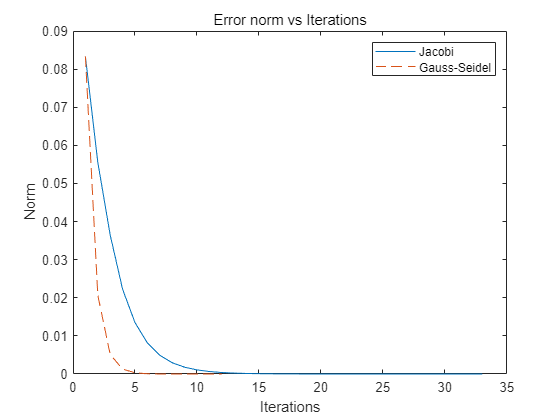

plot(1:itrj,normValj,1:itrg,normValg,'--')  %plot error norm vs iterations
legend('Jacobi','Gauss-Seidel')
title("Error norm vs Iterations")
xlabel("Iterations")
ylabel("Norm")

How did I implemented: I constructed this problem for 3 different parts of the diagonal, and set the vector and the tolerance, used the jacobi method and Gauss-seidel method to get the error and iterations.

 I used the formula which tought in class lecture to implement jacob function, with 2 for loops, which has time complexity O(n^2), if the iteration number is less or equal to tolerance, I break it out. 

For the Gauss method, the formula which also applied, and when i >1, I added additional for loops to do the same thing again to make sure the gauss value is correctly printing out.

c) Gauss-Seidel method uses latest updated values during each iteration while Jacobi’s Method uses values obtained in the last iteration. 

d) A sparse matrix is a matrix containing zero values mostly and few non-zero values. If A is diagonally dominant by rows as in case of sparse matrix, then the Jacobi and Gauss-Seidel methods converge for any initial guess.

## Problem 3: Understanding Gradient Descent

clear all, close all, clc, clf
format long

%% Steepest Descent example 
A=randi([1 1000],2,2); %2x2 matrix with random numbers between 1 and 1000
b=randi([1 1000],2,1); %2x1 matrix with random numbers between 1 and 1000
x=[0 0]'  %initial value of x

x =      0
     0


d = b;
normVal=Inf;
alpha = 0.5

alpha =    0.500000000000000


itr = 0;
tol = 0.1e-3;
%% Algorithm: Steepest Descent%%
fprintf(' %i   %6.3f   %6.3f   %6.3f   %6.3f   %6.3f \n',itr,x(1),x(2),d(1),d(2),alpha)

 0    0.000    0.000   832.000   804.000    0.500 


while normVal>tol
    xold=x;
    y = A*d;
    alpha  = (d'*d)/(d'*y);
    x = x + alpha*d;
    d = d - alpha*y;
    itr=itr+1;
    r(:,itr)=x;
    normVal=abs(xold-x); 
    fprintf(' %i   %6.3f   %6.3f   %6.3f   %6.3f   %6.3f \n',itr,x(1),x(2),d(1),d(2),alpha)
end

 1    2.155    2.082   288.739   -298.795    0.003 
 2    5.405   -1.281   600.933   580.709    0.011 
 3    6.961    0.223   208.549   -215.812    0.003 
 4    9.308   -2.206   434.039   419.432    0.011 
 5   10.432   -1.120   150.630   -155.876    0.003 
 6   12.128   -2.875   313.495   302.945    0.011 
 7   12.939   -2.090   108.796   -112.585    0.003 
 8   14.164   -3.358   226.430   218.810    0.011 
 9   14.750   -2.791   78.581   -81.317    0.003 
 10   15.635   -3.706   163.545   158.041    0.011 
 11   16.058   -3.297   56.757   -58.734    0.003 
 12   16.697   -3.958   118.124   114.149    0.011 
 13   17.003   -3.662   40.994   -42.422    0.003 
 14   17.465   -4.140   85.318   82.447    0.011 
 15   17.686   -3.926   29.609   -30.640    0.003 
 16   18.019   -4.271   61.623   59.549    0.011 
 17   18.178   -4.117   21.386   -22.131    0.003 
 18   18.419   -4.366   44.509   43.011    0.011 
 19   18.534   -4.255   15.446   -15.984    0.003 
 20   18.708   -4.435   32.14

%%
X=A\b; %exact solution
fprintf('Solution of the system is : \n%f  %f\n  residual %f  %f\n in %d iterations\n true solution is\n %d %d',x,d,itr,X);

Solution of the system is : 
19.459396  -4.612651
  residual 0.012031  -0.012450
 in 63 iterations
 true solution is
 1.946012e+01 -4.612930e+00

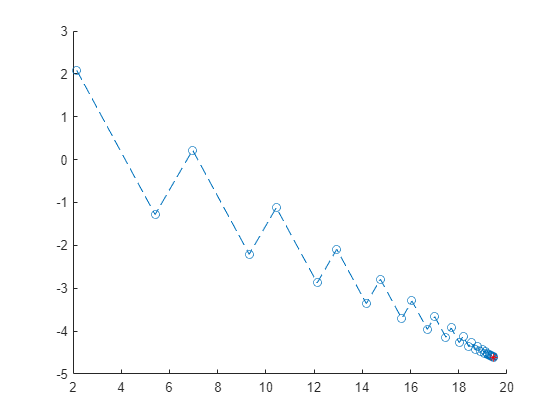

hold on
plot(r(1,:),r(2,:),'--o',X(1),X(2),'*r')

How did I implemented: By starting point from lecture, I added a while loop to keep track of the alpha, x and d, and do the absolute value to them. 

e) Yes, it converges with exact solution. For this part i was getting converged solution with true solution every time

f) After commenting out the alpha, solution does not always converge with the exact solution. When the value of alpha is around 0.0001, it took more time to complete the process and the solution is obtained in very few cases. When the value of alpha is increased around 0.1 to 0.9, the process completes quickly without giving any solution. The commented out formula updates the value of alpha for each iteration so that solution is obtained in fewest iterations.

## Problem 4: Gradient Descent

%% Add code and plot for this problem to problem 2
clear all, close all, clc, clf
d(1:8)=12; %values of diagonal fo matrix A
s(1:7)=3;  %values of first superdiagonal and subdiagonal of A
o(1:6)=1;  %values of second superdiagonal and subdiagonal of A
A=diag(d)+diag(s,1)+diag(s,-1)+diag(o,2)+diag(o,-2); %Create A
b=ones(8,1);  %vector b
tol=10^-8;  %tolerance
max_it=1000;  %maximum iterations
[xj,itrj,normValj]=jacobi(A,b,tol,max_it)

xj =    0.066711689220786
   0.050359367562931
   0.048381653780344
   0.050407605643365
   0.050407605643365
   0.048381653780344
   0.050359367562931
   0.066711689220786


itrj =     33


normValj =    0.083333333333333
   0.055555555555556
   0.036458333333333
   0.022231867283951
   0.013487011316872
   0.008144383894890
   0.004907176327803
   0.002958191038904
   0.001781821390214
   0.001073672140815


[xg,itrg,normValg]=gauss_seidel(A,b,tol,max_it)

xg =    0.066711688499612
   0.050359364873436
   0.048381650551624
   0.050407602300607
   0.050407602099286
   0.048381650654463
   0.050359365212567
   0.066711687808986


itrg =     12


normValg =    0.083333333333333
   0.020688657407407
   0.005099575215406
   0.001290928788745
   0.000317435122442
   0.000057640634064
   0.000007494288207
   0.000001609822795
   0.000000417382137
   0.000000053018486


[xs,itrs,normVals]=steepest_descent(A,b,tol,max_it)

alpha =      0


xs =    0.066711687195135
   0.050359367897734
   0.048381649389742
   0.050407603984718
   0.050407603984718
   0.048381649389742
   0.050359367897734
   0.066711687195135


itrs =     17


normVals =    0.053333333333333
   0.011451051596308
   0.002454439928136
   0.000666778712532
   0.000246215745643
   0.000098672182242
   0.000031605822737
   0.000014989650499
   0.000005456152048
   0.000002406085024


[xsm,itrsm,normValsm]=steepest_descent_mm(A,b,tol,max_it)

alpha =    0.005500000000000


beta =    0.915000000000000


xsm =    0.045673674616237
   0.041055010724601
   0.042303643817470
   0.044169191602089
   0.044169191602089
   0.042303643817470
   0.041055010724601
   0.045673674616237


itrsm =    180


normValsm =    0.053333333333333
   0.076643970343471
   0.068719953677055
   0.058157135492442
   0.058247994759712
   0.049704407549013
   0.049776895554634
   0.042315018952368
   0.042234461392331
   0.035709444580626


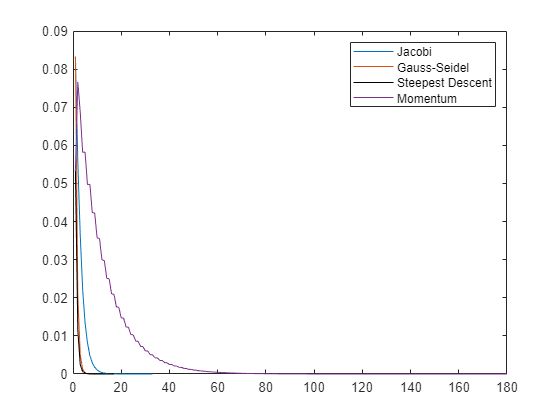

plot(1:itrj,normValj,1:itrg,normValg,1:itrs,normVals,'k',1:itrsm,normValsm)
legend('Jacobi','Gauss-Seidel','Steepest Descent','Momentum')

How did I implemented: added the Descent and momentum.

The descent method did same thing as Q3, set a while loop to track the value and break out when value less or equal to tolenrance.

The momentum, I set the alpha and beta value and do the same thing as the descent ones.

e) Both graphs are similar.

alpha = 0.0055

alpha =    0.005500000000000



beta = 0.915

beta =    0.915000000000000


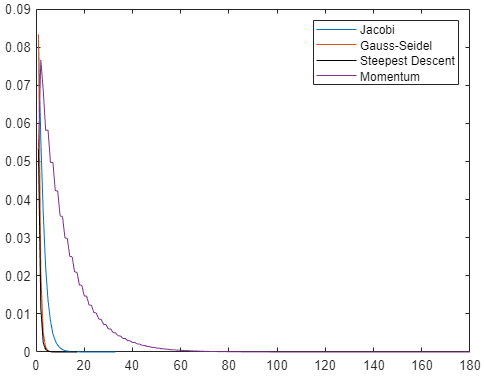

alpha = 0.001

alpha =      1.000000000000000e-03



beta = 0.1

beta =    0.100000000000000


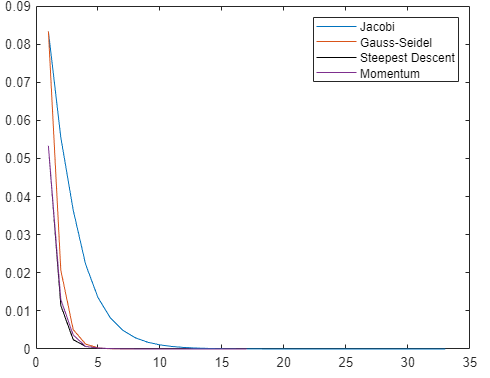

## Functions

**jacobi.m**

function [x,itr,normVal] = jacobi(A,b,tol,max_it)
itr=1;
n=length(A);
XO=zeros(n,1);
while itr<=max_it
    for i=1:n
        f=0;
        for j=1:n            
            if j~=i                
                f=f+(A(i,j)*XO(j,1));
            end
        end 
        x(i,1)=1/A(i,i)*(-f+b(i));

    end

    err=abs(x-XO);
    normVal(itr,1)=norm(err,"inf");

    if normVal(itr,1)<=tol
        break;
    end
    XO=x;
    itr=itr+1;
end
end

**gauss_seidel.m**

function [x,itr,normVal] = gauss_seidel(A,b,tol,max_it)
itr=1;
n=length(A);
XO=zeros(n,1);
while itr<=max_it
    for i=1:n
        f=0;
        for j=i+1:n
            f=f+A(i,j)*XO(j,1);
        end

        if i>1
            for j=1:i-1
                f=f+A(i,j)*x(j,1);
            end
        end
        x(i,1)=1/A(i,i)*(-f+b(i));
    end

    err=abs(x-XO);
    normVal(itr,1)=norm(err,"inf");

    if normVal(itr,1)<=tol
        break;
    end
    XO=x;
    itr=itr+1;
end
end

**steepest_descent.m**

function [x,itr,normVal] = steepest_descent(A,b,tol,max_it)
itr=1;
n=length(A);
x=zeros(n,1);
d = b;
alpha = 0.0
%% Algorithm: Steepest Descent%%
while itr<=max_it
    xold=x;
    y = A*d;
    alpha  = (d'*d)/(d'*y);
    x = x + alpha*d;
    d = d - alpha*y;
    err=abs(x-xold);
    normVal(itr,1)=norm(err,"inf");

    if normVal(itr,1)<=tol
        break;
    end    
    itr=itr+1;
end
end

**steepest_descent_mm.m**

function [x,itr,normVal] = steepest_descent_mm(A,b,tol,max_it)
itr=1;
n=length(A);
x=zeros(n,1);
d = b;
alpha = 0.0055

beta = 0.915

% alpha = 0.001
% beta = 0.1
z=0;
%% Algorithm: Steepest Descent%%
while itr<=max_it
    xold=x;
    y = A*d;
    alpha  = (d'*d)/(d'*y);
    z = -beta*z + d;
    x = x + alpha*z;
    d = d - alpha*y;
    err=abs(x-xold);
    normVal(itr,1)=norm(err,"inf");

    if normVal(itr,1)<=tol
        break;
    end    
    itr=itr+1;
end
end